clc;
clear all;

% Add statistical scripts to path
addpath('/Shared/boeslab/Users/jcgriffis/statistical_scripts/Misc_Code');
addpath('/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/final_archive_scripts');

% Path to adult SM model
sm_col = "gpb_dif";
sm_outcome = "contra_motor";    
sm_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/motor';    
sm_model_dir = 'plsr_all_lesion_d0_all_flip_ui';
sm_model_path = fullfile(sm_dir, sm_col, sm_model_dir); 

% Path to adult Lang model
lang_col = "mae_token";
lang_outcome = "worst_lang";    
lang_dir = '/Shared/boeslab/Users/jcgriffis/vips_psom_prediction/registry_models/language';   
lang_model_dir = 'plsr_all_lesion_d0_all_ui';    
lang_model_path = fullfile(lang_dir, lang_col, lang_model_dir); 

% Load cross-validation outputs
load(fullfile(sm_model_path, 'cv_results.mat'));
cv_sm = cv_results;
load(fullfile(lang_model_path, 'cv_results.mat'));
cv_lang = cv_results;

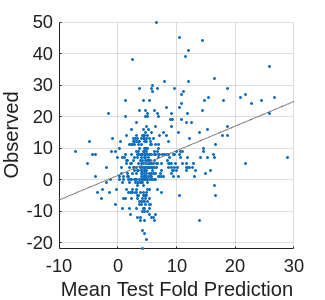

% Plot predicted vs. observed for all test folds averaged across repetitions and get CV correlations

% Plot predicted vs. observed for Grooved Peg-Board
scatter(nanmean(cv_sm.all.pred_y,2), cv_sm.all.obs_y, 50,'Marker', '.'); 
lsline;
set(gca,'FontSize', 14);
xlabel('Mean Test Fold Prediction');
ylabel('Observed'); axis('tight');
grid on; set(gcf, 'position', [0, 0, 325, 300]);

% Show CV correlation
[r, p] = corr(nanmean(cv_sm.all.pred_y,2), cv_sm.all.obs_y)

r = 0.3589

p = 1.5987e-15

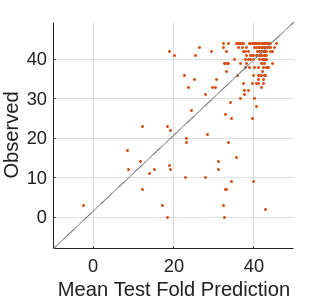

% Plot predicted vs. observed for Token Test
scatter(nanmean(cv_lang.all.pred_y,2).*-1, cv_lang.all.obs_y.*-1, 50, 'Marker', '.', 'MarkerEdgeColor', [0.85, 0.325, 0.098])
lsline;
set(gca,'FontSize', 14);
xlabel('Mean Test Fold Prediction');
ylabel('Observed'); axis('tight');
grid on; set(gcf, 'position', [0, 0, 325, 300]);

% Show CV Correlation
[r, p] = corr(nanmean(cv_lang.all.pred_y,2), cv_lang.all.obs_y)

r = 0.7143

p = 2.1503e-60